% 0. Initialize Parameters

n = 1251;               % Number of locations to evaluate bridge failure
L = 1250;               % Length of bridge
x = linspace(0, L, n);  % Define x coordinate
% SFD_PL = zeros(1, n)    % Initialize SFD(x)
total_loads = zeros(1, n); % Initialize total_loads for SFD(x)
y_zero = zeros(1,n);    % Initialize y-axis
BMD_PL = zeros(1,n);    % Initialize BMD(x)

%% 1. Point Loading Analysis (SFD, BMD)
P = -185;
[total_loads, BMD_PL] = ApplyPL(550, P, x, total_loads); % Construct SFD, BMD
[total_loads, BMD_PL] = ApplyPL(L, P, x, total_loads); % Construct SFD, BMD
SFD_PL = MakeSFD(total_loads)

SFD_PL =    55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491   55.8491


BMD_PL = MakeBMD(SFD_PL)

BMD_PL = 	1.0e+04 *

    0.0056    0.0112    0.0168    0.0223    0.0279    0.0335    0.0391    0.0447    0.0503    0.0558    0.0614    0.0670    0.0726    0.0782    0.0838    0.0894    0.0949    0.1005    0.1061    0.1117    0.1173    0.1229    0.1285    0.1340    0.1396    0.1452    0.1508    0.1564    0.1620    0.1675    0.1731    0.1787    0.1843    0.1899    0.1955    0.2011    0.2066    0.2122    0.2178    0.2234    0.2290    0.2346    0.2402    0.2457    0.2513    0.2569    0.2625    0.2681    0.2737    0.2792


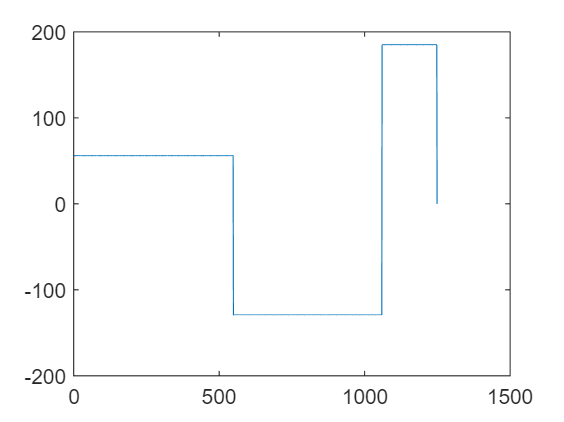

plot(x, SFD_PL)

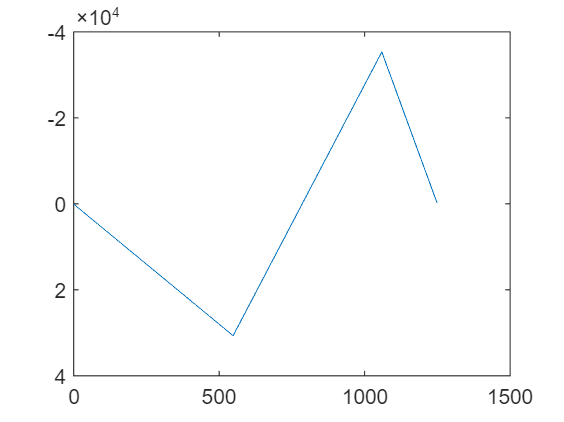

plot(x, BMD_PL)
set(gca,'YDir','reverse')


%% 2. Define cross-sections
% There are many (more elegant ways) to construct cross-section objects
xc = [0 550 L]; % Location, x, of cross-section change
bft = [100 100 100]; % Top Flange Width
tft = [2.54 2.54 2.54]; % Top Flange Thickness
hw = [100 120 100]; % Web Height
tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
bfb = [80 80 80]; % Bottom Flange Width
tfb = [1.27 1.27 1.27]; % Bottom Flange Thickness
a = [400 400 400]; % Diaphragm Spacing
% Optional but you need to ensure that your geometric inputs are correctly implemented
% VisualizeBridge( {CrossSectionInputs} ); 

%% 3. Define Material Properties
SigT = 30;
SigC = 6;
E = 4000;
TauU = 4;
TauG = 2;
mu = 0.2;

function [ total_loads, BMD_PL ] = ApplyPL( xP, P, x, total_loads )
% Constructs SFD and BMD from application of 1 Point Load. Assumes fixed location of supports
% Input: location and magnitude of point load. The previous SFD can be entered as input to construct SFD of multiple point loads
% Output: SFD, BMD both 1-D arrays of length n
% xP = distance from left (A) support (x = 0)
xP_B = 1060;
cur_P_B = -P * xP / xP_B; % P_B due to current P
P_A = total_loads(1) -P - cur_P_B; % Overall P_A
P_B = cur_P_B + total_loads(xP_B+1) - total_loads(xP_B); % Overall P_B

total_loads(1) = P_A;
total_loads(xP) = P;
total_loads(xP_B+1) = P_B;
BMD_PL = 0;
end

function [SFD_PL] = MakeSFD(total_loads)
    n = 1251;
    SFD_PL = zeros(1, n);
    SFD_PL(1) = total_loads(1);
    for i = 2:length(total_loads)
        SFD_PL(i) = total_loads(i) + SFD_PL(i-1);
    end
end

function [BMD_PL] = MakeBMD(SFD_PL)
    BMD_PL = cumsum(SFD_PL);
end